# STEADY ADVECTION-DIFFUSION PROBLEM: PGD Offline

## Oriol CHANDRE VILA

## ISAE-SUPAERO, June 2018

This code aims to compute a PGD for the problem of advection-diffusion in a square domain with fixed Dirichlet and Neumann BC. In this approach, the x-axis velocity, y-axis velocity and diffusivity parameter are defined as extra-coordinates of the problem.

clear all; close all; clc;
warning('off');

## Initializing the problem

Firstly, the problem's domain is defined. Also the data necessary to give to the problem its physical sense.

% VARIABLES
global num_max_iter max_fp_iter TOL TOL_TILDE ybar;
TOL = 1.0E-08; % Tolerance.
TOL_TILDE = 1.0E-06; % PGD enrichment tolerance.
num_max_iter = 1500; % Max. # of functional pairs for the approximation.
max_fp_iter = 200; % Max. # of iterations in the fixed point loop.

% GEOMETRY
Lx = 1; Ly = 1; Lv = 0.5; Lk = 0.025;
Nx = 61; Ny = 61; Nv = 21; Nk = 31;
x = linspace(0,Lx,Nx)';
y = linspace(0,Ly,Ny)';
vx = linspace(0,Lv,Nv)';
vy = linspace(0,Lv,Nv)';
k = linspace(0,Lk,Nk)';
ybar = 0.4;

% DIRICHLET BC
Td = zeros(Ny,1); % Temperature profile in the wall
for j = 1:Ny
    if y(j) < (y(end)/3) || y(j) > (2*y(end)/3)
        Td(j,1) = 300;
    else
        Td(j,1) = 300 + 325*(sin(3*pi*abs(y(j)-ybar))+1);
    end
end

## Offline PGD Solution

General purpose PGD function with residual minimization, not optimized for efficiency. Adaptation of the code presented in *The Proper Generalized Decomposition for Advanced Numerical Simulation: A primer* written by F. Chinesta, R. Keunings and A. Leygue. The author of the code is A. Leygue.

tic

hx = x(2)-x(1); hy = y(2)-y(1); % x & y mesh grid size

% 1D OPERATORS ALONG X & Y
% Identity matrices
Mx = speye(Nx); My = speye(Ny);
% 1st (upwind scheme) and 2nd (centered scheme) derivatives
D2x =  spdiags([ones(Nx,1) -2*ones(Nx,1) ones(Nx,1)],[-1 0 1],Nx,Nx)/hx^2;
D1x =  spdiags([-ones(Nx,1)  ones(Nx,1)],[-1  0],Nx,Nx)/hx;
D2y =  spdiags([ones(Ny,1) -2*ones(Ny,1) ones(Ny,1)],[-1 0 1],Ny,Ny)/hy^2;
D1y =  spdiags([-ones(Ny,1)  ones(Ny,1)],[-1  0],Ny,Ny)/hy;
% Neumann BC
D1x(end,end) = 0;
D1y(1,1) = 0; D1y(end,end) = 0;

% IDENTITY OPERATORS ALONG U, V & K
Mv = speye(Nv); Mk = speye(Nk);

% SOURCE TERM IN A SEPARATED FORM (f(x,y) = 0)
fx = zeros(Nx,1); fy = zeros(Nx,1);
% The extra-coordinates must not affect in the problem definition!
fvx = ones(Nv,1); fvy = ones(Nv,1); fk = ones(Nk,1);

% PROBLEM DEFINITION IN A MATRIX OPERATOR FORM:
% There will be 5 dimensions (x, y, u, v, k) solved for 2D.
AA = cell(5,4); % Operator. dim2: 2 diffusion eq. and 2 advection eq.
BB = cell(5,1); % RHS: in this problem is zero.
GG = cell(5,1); % A priori known terms, to enforce the Dirichlet BC
Dirichlet = cell(5,1); % Dirichlet BC: where to be applied.
N_NT = cell(5,1); % Mass matrices.

% CONSTRUCTION OF THE PROBLEM: (U*D1 - k*D2)*T = 0
% x-diffusion (-k*D2x)
AA{1,1} = -D2x; AA{2,1} = My; AA{3,1} = Mv; AA{4,1} = Mv;
AA{5,1} = spdiags(k,0,Nk,Nk);
% y-diffusion (-k*D2y)
AA{1,2} = Mx; AA{2,2} = -D2y; AA{3,2} = Mv; AA{4,2} = Mv;
AA{5,2} = spdiags(k,0,Nk,Nk);
% x-advection (u*D1x)
AA{1,3} = D1x; AA{2,3} = My; AA{3,3} = spdiags(vx,0,Nv,Nv);
AA{4,3} = Mv; AA{5,3} = Mk;
% y-advection (v*D1y)
AA{1,4} = Mx; AA{2,4} = D1y; AA{3,4} = Mv;
AA{4,4} = spdiags(vy,0,Nv,Nv); AA{5,4} = Mk;
% RHS
BB{1} = [fx 0*ones(Nx,1)]; BB{2} = [fy ones(Ny,1)];
BB{3} = [fvx ones(Nv,1)]; BB{4} = [fvy ones(Nv,1)];
BB{5} = [fk ones(Nk,1)];
% GG
GG{1} = ones(Nx,1); GG{2} = Td; GG{3} = ones(Nv,1);
GG{4} = ones(Nv,1); GG{5} = ones(Nk,1);

% Imposition of a Dirichlet BC on the whole boundary: just to remember, in
% our problem, x = 1, y = 0 and y = 1 are represented by Neumann BC. The
% only Dirichlet BC is located in x = 0.
Dirichlet{1} = [1];
N_NT{1} = Mx; N_NT{2} = My; N_NT{3} = Mv; N_NT{4} = Mv; N_NT{5} = Mk;

% PGD SOLUTION (with stabilization thanks to the upwind scheme)
[FF] = PGD_SYM(AA,BB,GG,N_NT,Dirichlet);
temps_Offline = toc

temps_Offline = 2.9396e+03

fprintf(1,'PGD offline Process exited normally\n');

PGD offline Process exited normally


save('WorkSpacePGD_AdvDiffSteady.mat');

The workspace is saved in order to run the Online code independently!

## Post-Process

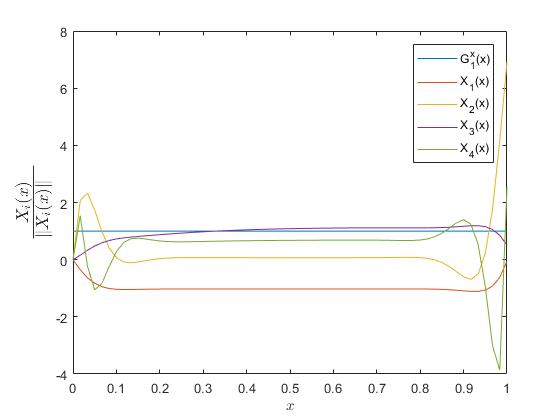

figInt = 0;
% NORMALIZATION OF THE COMPUTED FUNCTIONS
Xnorm = bsxfun(@rdivide,FF{1},sqrt(trapz(x,FF{1}.^2)));
Ynorm = bsxfun(@rdivide,FF{2},sqrt(trapz(y,FF{2}.^2)));
Unorm = bsxfun(@rdivide,FF{3},sqrt(trapz(vx,FF{3}.^2)));
Vnorm = bsxfun(@rdivide,FF{4},sqrt(trapz(vy,FF{4}.^2)));
Knorm = bsxfun(@rdivide,FF{5},sqrt(trapz(k,FF{5}.^2)));

if size(Xnorm,2) < 5
    j = size(Xnorm,2);
else
    j = 5;
end

% G_1^x, X_i PLOT
figInt = figInt + 1;
figure(figInt);
set(gca,'fontsize',14);
handles = plot(x,Xnorm(:,1:j));
legend(handles,[{'G_1^x(x)'} cellfun(@(in) ['X_' num2str(in) '(x)'],...
    num2cell(1:j-1),'uniformoutput',false)]);
xlabel('$x$','interpreter','latex');
ylabel('$\frac{X_i(x)}{\|X_i(x)\| \,\,\, \,\,}$','interpreter',...
    'latex','fontsize',18);

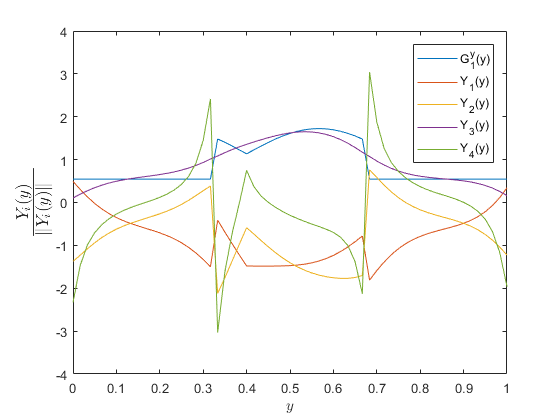


% G_i^y, Y_i PLOT
figInt = figInt + 1;
figure(figInt);
set(gca,'fontsize',14);
handles = plot(y,Ynorm(:,1:j));
legend(handles,[{'G_1^y(y)'} cellfun(@(in) ['Y_' num2str(in) '(y)'],...
    num2cell(1:j-1),'uniformoutput',false)]);
xlabel('$y$','interpreter','latex');
ylabel('$\frac{Y_i(y)}{\|Y_i(y)\| \,\,\, \,\,}$','interpreter',...
    'latex','fontsize',18);

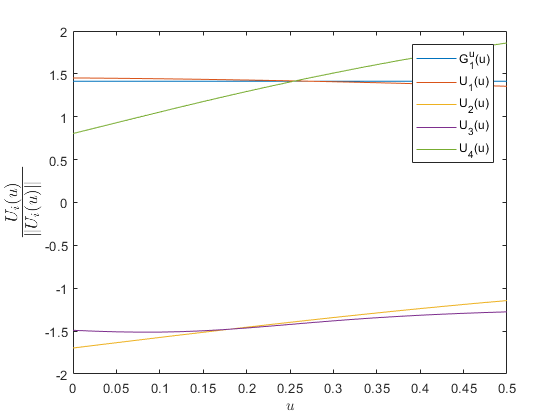


% G_i^u, U_i PLOT
figInt = figInt + 1;
figure(figInt);
set(gca,'fontsize',14);
handles = plot(vx,Unorm(:,1:j));
legend(handles,[{'G_1^u(u)'} cellfun(@(in) ['U_' num2str(in) '(u)'],...
    num2cell(1:j-1),'uniformoutput',false)]);
xlabel('$u$','interpreter','latex');
ylabel('$\frac{U_i(u)}{\|U_i(u)\| \,\,\, \,\,}$','interpreter',...
    'latex','fontsize',18);

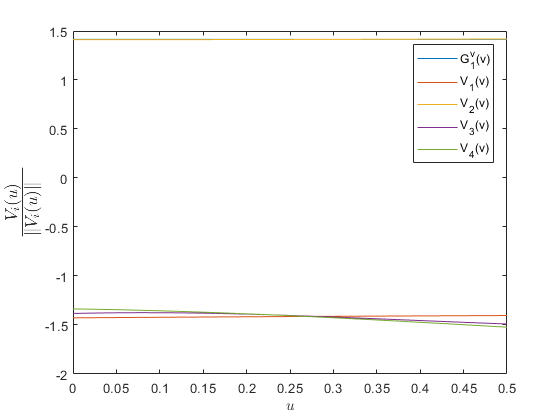


% G_i^v, V_i PLOT
figInt = figInt + 1;
figure(figInt);
set(gca,'fontsize',14);
handles = plot(vy,Vnorm(:,1:j));
legend(handles,[{'G_1^v(v)'} cellfun(@(in) ['V_' num2str(in) '(v)'],...
    num2cell(1:j-1),'uniformoutput',false)]);
xlabel('$u$','interpreter','latex');
ylabel('$\frac{V_i(u)}{\|V_i(u)\| \,\,\, \,\,}$','interpreter',...
    'latex','fontsize',18);

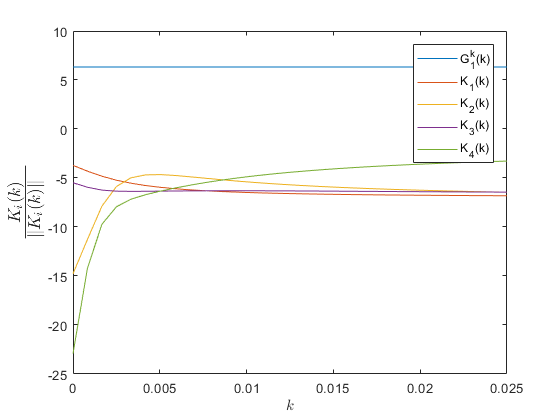


% G_i^k, K_i PLOT
figInt = figInt + 1;
figure(figInt);
set(gca,'fontsize',14);
handles = plot(k,Knorm(:,1:j));
legend(handles,[{'G_1^k(k)'} cellfun(@(in) ['K_' num2str(in) '(k)'],...
    num2cell(1:j-1),'uniformoutput',false)]);
xlabel('$k$','interpreter','latex');
ylabel('$\frac{K_i(k)}{\|K_i(k)\| \,\,\, \,\,}$','interpreter',...
    'latex','fontsize',18);

## Appendices

## function *PGD_SYM.m*

function [FF] = PGD_SYM(AA,BB,GG,N_NT,Dirichlet)
% This specific implementation relies on the fact that the residual
% minimization algorithm can be implemented as the original PGD
% algorithm (as in PGD.m) applied on a symetrized problem.
% Outputs:
%       FF :  A cell array of matrices. The d^th element is a matrix whose
%       columns contains all the enrichment functions computed for that
%       dimension.
% Inputs:
%       AA: cell array of matrices. We assume that the differential operator
%       is written as a sum of simple multidimensional operators that can be
%       written as the tensorial product of operators along each of the PGD
%       dimensions.
%       The i^th column of AA contains the discretized form (matrix) of
%       those operator whose tensorial product yield the i^th simple
%       multidimensional operator.
%
%       BB: separated form of the right hand side
%
%       GG: separated form of the a priori known terms of the PGD solution
%
%       N_NT: cell array of matrices that are used to compute the
%       appropriate L2 norm along each PGD dimension
%
%       Dirichlet: cell array of vectors indicating for each dimension the
%       nodal values to which one has to apply homogeneous Dirichlet
%       boundary conditions
%
%
% Copyright (c) 2013, Francisco Chinesta (Ecole Centrale de Nantes), 
% Roland Keunings (Universite catholique de Louvain), Adrien Leygue(CNRS)
% Author: Adrien Leygue.
% All rights reserved.
% See License file for more details

%% PARAMETERS DEFINTION
Ndims = size(AA,1); % # of separated PGD dimensions
Nops = size(AA,2); % # of simple multidimensional operators
Nvars = zeros(1,Ndims); % # of variables along each PGD dimension
for d = 1:Ndims
    Nvars(d) = size(AA{d,1},1);
end
% IDENTIFICATION OF THE VARIABLES SUBJECTED TO DIRICHLET BC
mask =  cellfun(@(dummy) true(dummy,1),num2cell(Nvars),'uniformoutput',0);
for d = 1:Ndims
    mask{d}(Dirichlet{d}) = false;
end

%% TRANSFORMATION OF THE PROBLEM
% We transform the problem to have the residual minimization form with
% no Dirichlet BC: all known enrichments are passed to te right hand
% side and the dofs subject to a homogeneous Dirichlet BC are removed
% from the problem

% NEW PROBLEM INITIALIZATION
AA_new = cell(Ndims,Nops^2); 
BB_new = cell(Ndims,1); BB_tmp = cell(Ndims,1);
GG_new = cell(Ndims,1); N_NT_new = cell(Ndims,1);
Dirichlet_new = cell(Ndims,1);
% REMOVAL OF DIRICHLET DOFS IN BB and N_NT: We search for the values of BB
% and N_NT in the Dirichlet dofs!!
for d = 1:Ndims
    BB_tmp{d} = BB{d}(mask{d},:);
    N_NT_new{d} = N_NT{d}(mask{d},mask{d});
end
% INCORPORATION OF GG INTO BB (Dirichlet BC are now in the RHS)
if(size(GG{1},2) > 0)
    for i = 1:Nops
        % Specific treatment to force the 1st term to be (-)
        BB_tmp{1} = [BB_tmp{1} -AA{1,i}(mask{1},:)*GG{1}];
    end
    for d = 2:Ndims
        for i = 1:Nops
            BB_tmp{d} = [BB_tmp{d} AA{d,i}(mask{d},:)*GG{d}];
        end
    end
end

%% SYMETRIZATION OF THE PROBLEM
% The tranpose of the operators is applied on BB and on the operators
% themselves
for d = 1:Ndims
    BB_new{d} = zeros(nnz(mask{d}),0);
    for i=1:Nops
        BB_new{d} = [BB_new{d} AA{d,i}(mask{d},mask{d})'*BB_tmp{d}];
        for j=1:Nops
            AA_new{d,(i-1)*Nops+j} = AA{d,i}(mask{d},mask{d})'*...
                AA{d,j}(mask{d},mask{d});
        end
    end
end

%% PGD SOLUTION OF THE MODIFIED PROBLEM
FF_new = PGD(AA_new,BB_new,GG_new,N_NT_new,Dirichlet_new);
% ADDING THE PREVIOUSLY REMOVED DIRICHLET DOFS
FF = cell(Ndims,1);
Nterms = size(FF_new{1},2);
for d=1:Ndims
    tmp = zeros(Nvars(d),Nterms);
    tmp(mask{d},:) = FF_new{d};
    FF{d} = [GG{d} tmp;];
end
end

## function *PGD.m*

function [FF] = PGD(AA,BB,GG,N_NT,Dirichlet)
% General purpose PGD function, not optimized for efficiency
% Outputs:
%       FF :  A cell array of matrices. The d^th element is a matrix whose
%       columns contains all the enrichment functions computed for that
%       dimension.
% Inputs:
%       AA: cell array of matrices. We assume that the differential operator
%       is written as a sum of simple multidimensional operators that can be
%       written as the tensorial product of operators along each of the PGD
%       dimensions.
%       The i^th column of AA contains the discretized form (matrix) of
%       those operator whose tensorial product yield the i^th simple
%       multidimensional operator.
%
%       BB: separated form of the right hand side
%
%       GG: separated form of the a priori known terms of the PGD solution
%
%       N_NT: cell array of matrices that are used to compute the
%       appropriate L2 norm along each PGD dimension
%
%       Dirichlet: cell array of vectors indicating for each dimension the
%       nodal values to which one has to apply homogeneous Dirichlet
%       boundary conditions
%
%
% Copyright (c) 2013, Francisco Chinesta (Ecole Centrale de Nantes), 
% Roland Keunings (Universite catholique de Louvain), Adrien Leygue(CNRS)
% Author: Adrien Leygue.
% All rights reserved.
% See License file for more details

global num_max_iter max_fp_iter TOL TOL_TILDE;

%% PARAMETERS DEFINTION
Ndims = size(AA,1); % # of separated PGD dimensions
Nops = size(AA,2); % # of simple multidimensional operators
Nb = size(BB{1},2); % # of terms in the separated representation of the RHS
N0 = size(GG{1},2); % # of a priori known terms in the solution
Nvars = zeros(1,Ndims); % # of variables along each PGD dimension
for i=1:Ndims
    Nvars(i) = size(AA{i,1},1);
end
% AUXILIARY FUNCTION: Used to compute the multidimensional integral of f*g
% where both have a separated representation with one term
aux_int = @(f,g) prod(cellfun(@(a,b,c) a'*b*c,f,N_NT,g));

%% INITIALIZING THE SOLUTION
FF = cell(Ndims,1);
% ADDING GG to FF
for i = 1:Ndims
    FF{i} = GG{i};
end

%% ENRICHMENT LOOP
for term = (N0+1):num_max_iter
    % RS INITIALIZATION
    RS = cell(Ndims,1);
    for i = 1:Ndims
        RS{i} = randn(Nvars(i),1);
        RS{i}(Dirichlet{i}) = 0; % Applying Dirichlet BC
    end
    % FIXED POINT ITERATIONS
    for iter = 1:max_fp_iter
        RS_old = RS;
        % UPDATE EACH ALONG EACH DIMENSION
        for i = 1:Ndims
            mask = [(1:i-1) (i+1:Ndims)]; % Which are the "other" dims?
            % CONSTRUCTION OF THE LHS
            K = sparse(Nvars(i),Nvars(i));
            for j = 1:Nops
                factor_K = 1; % Computation of the pre-factor
                for tmp_dim = mask
                    factor_K = factor_K * (RS{tmp_dim}'*AA{tmp_dim,j}...
                        *RS{tmp_dim});
                end
                K = K + factor_K*AA{i,j}; % Assemblying the LHS
            end
            % CONSTRUCTION OF THE RHS
            factors_b = ones(1,Nb); % Initially, BB
            for tmp_dim = mask
                factors_b = factors_b .* (RS{tmp_dim}'*BB{tmp_dim});
            end
            b = BB{i}*factors_b.';
            if(term > 1) % Adding known modes of FF
                for j = 1:Nops
                    factors_b = ones(1,term-1);
                    for tmp_dim = mask
                        factors_b = factors_b .* ( RS{tmp_dim}'*...
                            AA{tmp_dim,j}*FF{tmp_dim});
                    end
                    b = b -(AA{i,j}*FF{i})*factors_b.';
                end
            end
            % APPLICATION OF THE DIRICHLET BOUNDARY CONDITIONS
            tmp = true(Nvars(i),1); tmp(Dirichlet{i}) = false;
            % SOLUTION
            RS{i}(tmp) = K(tmp,tmp)\b(tmp);
        end
        % STOPPING CRITERION: Fixed point termination test
        S_diff = sqrt(aux_int(RS,RS) + aux_int(RS_old,RS_old) - ...
            2*aux_int(RS,RS_old))/sqrt(aux_int(RS,RS));
        if (S_diff < TOL)
            break;
        end
    end
    
    % UPDATING FF WITH RS
    for i = 1:Ndims
        FF{i} = [FF{i} RS{i}];
    end
    % STOPPING CRITERION: Enrichment loop termination test
    if term == (N0+1)
        Enrichment_1st = cellfun(@(a) a(:,term),FF,'uniformoutput',false);
    end
    Error_iter = sqrt(aux_int(RS,RS))/ sqrt(aux_int(Enrichment_1st,...
        Enrichment_1st));
    if (Error_iter < TOL_TILDE)
        fprintf(1,'TOL_TILDE reached! \n');
        break;
    end
end
end